# **Optimal Policies With Dynamic Programming**

## Gridworld

Tenemos un espacio físico dividido en la forma de una cuadrícula. El agente tiene la tarea de navegar hasta una celda específica a la que se le denomina meta. Las acciones que puede tomar el agente consisten de las diferentes direcciones en las que se puede movilizar el mismo. Los estados consisten de las diferentes posiciones que puede ocupar el agente en la cuadrícula y los estados futuros consisten de las casillas en las que el agente caerá luego de movilizarse. En estados "extremos" (En los bordes de la cuadrícula) el agente vuelve a caer en el mismo estado si la acción conllevara a que el mismo se saliera de la cuadrícula. 

clear;

% Dimensiones del grid en el que se desplazará el agente.
AnchoGrid = 3;
AltoGrid = 3;

% Estados de (1,NoEstados)
Estados = 1:(AnchoGrid * AltoGrid);
NoEstados = numel(Estados);
MatrizEstados = reshape(Estados,AltoGrid,AnchoGrid)

MatrizEstados =      1     4     7
     2     5     8
     3     6     9


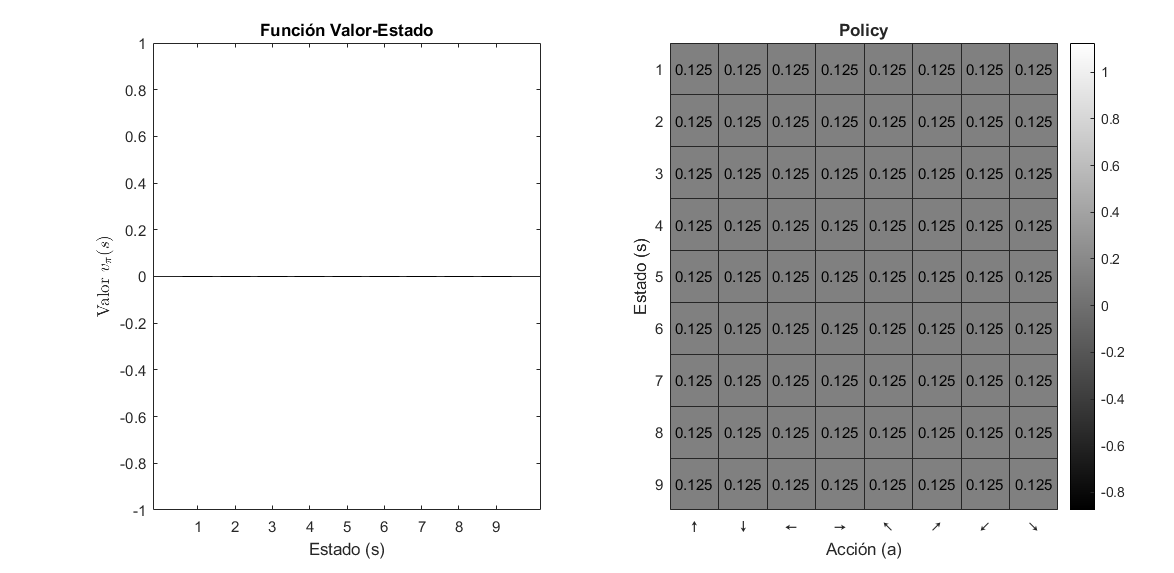


% Estados meta donde se acaban los episodios
EstadosMeta = [64]';
EstadosObs = [21 22 28 37 90 89 99 100 45 42 43 46 56 47 57 24 25 35]';
EstadosObs = [2 4 6 8]';
EstadosMeta = [1 3 7 9]';
EstadosObs(EstadosObs > max(Estados)) = [];

% Acciones
% 1: Arriba / 2: Abajo / 3: Izquierda / 4: Derecha
% 5: Arriba-izquierda / 6: Arriba-derecha
% 7: Abajo-izquierda / 8: Abajo-derecha
Direcciones = 8;
Acciones = 1:Direcciones;
NoAcciones = numel(Acciones);

% Policy
% Igual probabilidad de moverse en alguna de las direcciones disponibles.
Policy = ones(NoEstados,NoAcciones) / Direcciones;

% Inicialización de valor de estados
V = zeros(size(Estados));

% Gráfica de la función de valor y la policy
% - Función de valor: Mayor valor implica un mejor estado
% - Policy: Probabilidad de tomar una acción en un estado
figure(1); clf;
PlotStateSpace(Estados,Acciones,Policy,V);

## Policy Iteration

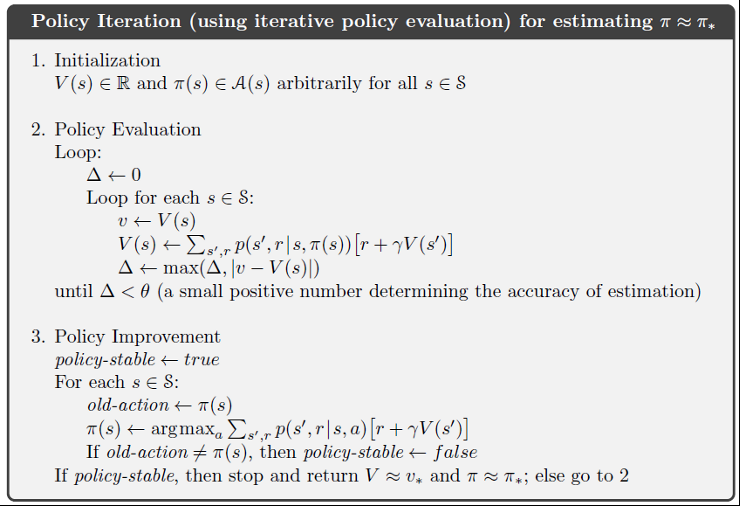

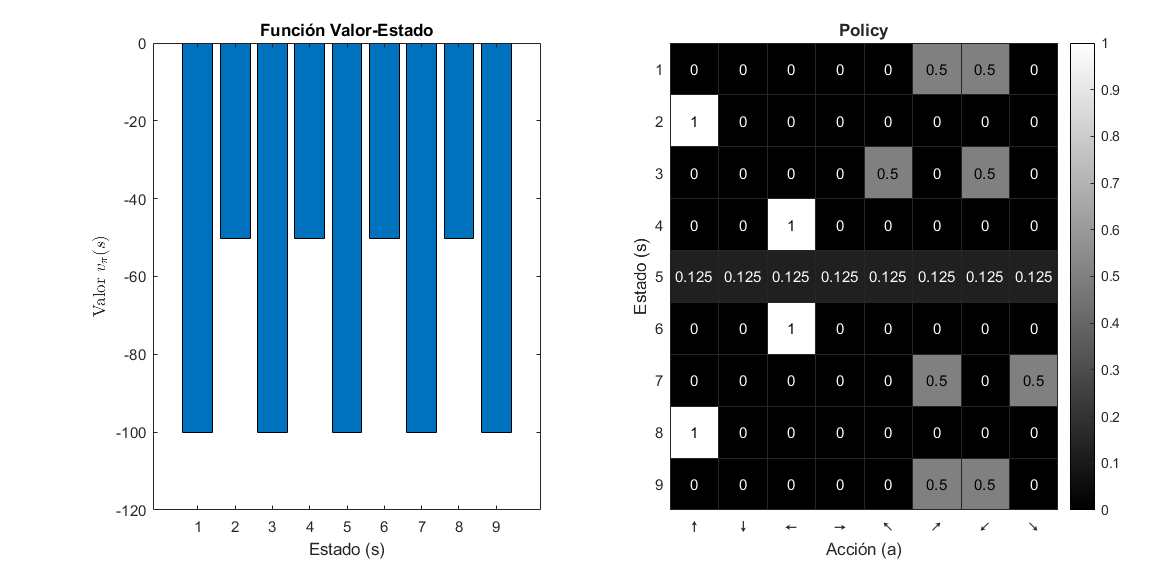

% Discount factor
% Valor entre 0 y 1. Mientras más se acerque a 1, el agente se enfoca más
% en las recompensas y acciones futuras. Con 0, el agente solo mira su
% futuro directamente frente a él (Se torna miope).
Gamma = 0.99;

% Dependiendo de la complejidad del escenario a trabajar, el algoritmo
% puede converger muy rápido o atorarse en un ciclo en el que alterna entre
% policies igualmente "óptimas". Para evitar esto, se coloca un límite de
% iteraciones para el algoritmo. 
IteracionActual = 1;
IteracionesMax = 101;

% Mientras la policy no sea estable (Mientras la probabilidad de tomar una
% acción no cambie de iteración a iteración), se continuará el ciclo de
% evaluación y mejora
PolicyEstable = 0;
while ~PolicyEstable

    % Policy Evaluation
    ThresholdPrecisionPolicy = 0.0001;
    Delta = 1;                                  % Valor grande para que siempre se ejecute el while de abajo
    
    while Delta > ThresholdPrecisionPolicy
        Delta = 0;
        q = zeros(size(Policy));
        
        for s = Estados
            V_Old = V(s);
            
            % Se calcula el valor de acción o el valor por tomar una acción en
            % un estado específico
            for a = Acciones
               [Recompensa,EstadoFuturo] = DinamicaGrid(a,s,MatrizEstados,EstadosMeta,EstadosObs);
               q(s,a) = (Policy(s,a) * (Recompensa + Gamma*V(EstadoFuturo)));
            end
            
            % El valor de un estado es la suma de todos los valores de acción
            V(s) = sum(q(s,:));
            Delta = max(Delta,abs(V_Old - V(s)));
            
        end   
        
    end

    % Policy Improvement
    for s = Estados
        Policy_Old = Policy;                        % Se guardan las probabilidades de acción previas
        
        qMax = max(q(s,:));                         % Se obtiene el valor de acción más alto.
        AccionesOptimas = find(q(s,:) == qMax);     % Acciones correspondientes al valor más alto
        
        Policy(s,:) = 0;                            % Igual probabilidad de tomar las acciones óptimas
        Policy(s,AccionesOptimas) = 1 / numel(AccionesOptimas); 
    end
    
    if Policy_Old == Policy                         % Si no cambia la policy luego de haberla "maximizado"
        PolicyEstable = 1;
    end
    
    IteracionActual = IteracionActual + 1;
    
    % Si se alcanza el número máximo de iteraciones, se finaliza el proceso
    % de iteración 
    if IteracionActual == IteracionesMax
        break;
    end
    
end

% Gráfica de la función de valor y la policy
figure(2); clf;
PlotStateSpace(Estados,Acciones,Policy,V);

## Visualización de Policy Óptima Sobre GridWorld

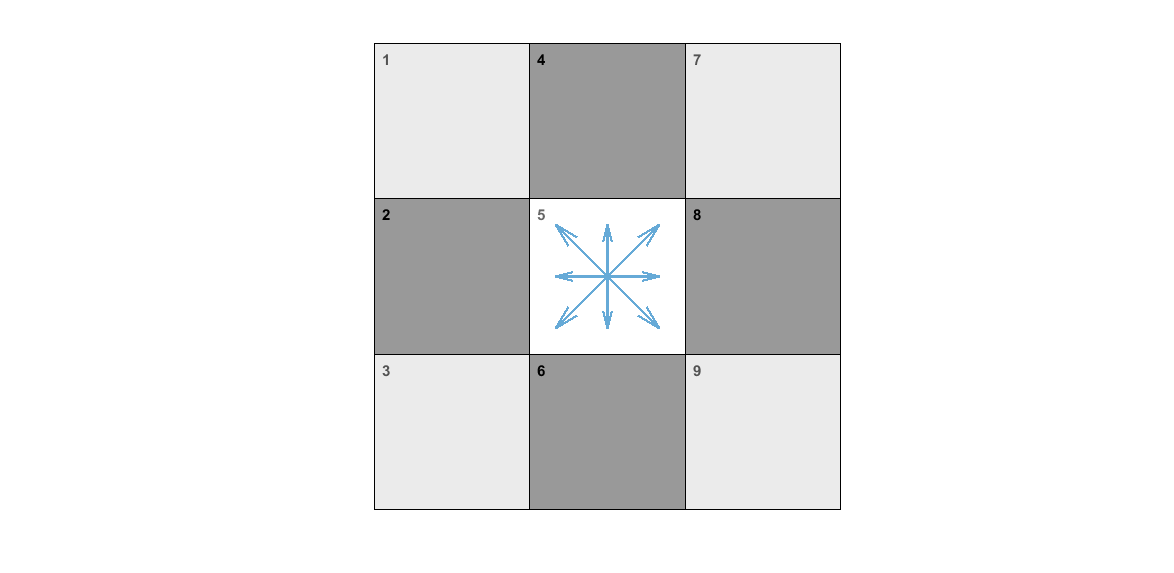

% Componentes direccionales para las flechas que se van a graficar
% utilizando "quiver()" para representar las ocho acciones que puede tomar
% el agente.
Direcciones = [ 0  1    % Arriba
                0 -1    % Abajo
               -1  0    % Izquierda
                1  0    % Derecha
               -1  1    % Arriba-izquierda
                1  1    % Arriba-derecha
               -1 -1    % Abajo-izquierda
                1 -1];  % Abajo-derecha
            
% Se escala el tamaño de las flechas
Direcciones = Direcciones / 3;
            
% De la policy, se extraen todas las acciones que tengan una probabilidad
% distinta de 0. Específicamente se extrae el estado en que ocurre la acción
% y el índice de la acción como tal. "find(Policy)" aquí hace lo mismo que
% "find(Policy ~= 0)".
[EstadosOptimos, AccionesOptimas] = find(Policy);

% Vector que contiene las policies o las direcciones en las que se puede
% mover el agente.
CompsFlechas = zeros(numel(EstadosOptimos),2);

% Posición en la que inician todas las colas de las flechas.
PosColasFlechas = zeros(numel(EstadosOptimos),2);

for i = 1:numel(EstadosOptimos)
    
    % Componentes (X,Y) de la flecha actual
    CompsFlechas(i,:) = Direcciones(AccionesOptimas(i),:);
    
    % Posiciones de las colas de las flechas (Fila y columna dentro de la
    % grid que corresponde al estado dado).
    [FilaEstado, ColEstado] = find(MatrizEstados == EstadosOptimos(i));
    PosColasFlechas(i,:) = [ColEstado FilaEstado];
    
    % Si el estado óptimo actual "i" es un obstáculo o meta, no se le
    % grafica una flecha de policy.
    if ismember(EstadosOptimos(i),EstadosMeta) || ismember(EstadosOptimos(i),EstadosObs)
        CompsFlechas(i,:) = 0;
    end
end


% Las posiciones de las colas de las flechas están dadas en términos 
% de su número de fila y columna dentro de la matriz de estados. Esto
% implica que, para un grid de 3x3, las coordenadas del estado 1 serán
% (1,1) ya que ocupa la fila 1, columna 1 en la matriz de estados. 
% 
%       C1  C2  C3 
%   F1   1   4   7
%   F2   2   5   8
%   F3   3   6   9
% 
% Lo malo es que los bordes de la grid se grafican en el plano cartesiano o
% con su esquina inferior izquierda en la coordenada (0,0). Entonces, si se
% grafica la cola de la flecha en (1,1), esta no aparecerá centrada en el
% estado 1, sino en el estado 3. El estado 1, está en realidad en la coord.
% (1,3) del plano cartesiano.
% 
%   Y3   1   4   7
%   Y2   2   5   8
%   Y1   ↗   6   9
%       X1  X2  X3
% 
% Para corregir esto, se hace un flip vertical colocando todas las
% coordenadas en Y negativas, y luego sumándoles el alto de la grid + 1.
% Ahora la coordenada Y del estado 1 (Y = 1), es igual a
% (-1) + 3 + 1 = 3.

PosColasFlechas(:,2) = - PosColasFlechas(:,2) + AltoGrid + 1;

% Ahora solo tenemos un último problema. Las celdas de la cuadrícula tienen
% un largo y alto unitario. Esto implica que una flecha graficada en la
% coordenada (1,1) va a graficarse en la esquina superior derecha del
% estado 3 del ejemplo. Para centrar la flecha, le realizamos un desfase en
% X y Y, de 0.5 positivo.

PosColasFlechas = PosColasFlechas + 0.5;

% Setup de gráfica
figure(3); clf; hold on;

% Graficación de Cuadrícula
Cuadricula = ones(size(MatrizEstados));                     % Matriz de 1's (blanca) 
Cuadricula(EstadosMeta) = 0.8;                              % Gris claro para metas
Cuadricula(EstadosObs) = 0;                                 % Gris oscuro para los obstáculos 
Cuadricula = flipud(Cuadricula);                            % Se hace un mirror en Y para que los colores aparezcan donde son
Cuadricula = [Cuadricula zeros(AltoGrid,1)];                % Se agrega padding a la derecha o la gráfica no muestra cuadricula a la derecha
Cuadricula = [Cuadricula; zeros(1,AnchoGrid+1)];            % Se agrega padding abajo o la gráfica no muestra cuadrícula en la primera fila

% Gráfica de la cuadrícula y las celdas coloreadas
PlotObstaculosMetas = surface(Cuadricula,'FaceAlpha',0.4);

% Se grafican las flechas
PlotPolicy = quiver(PosColasFlechas(:,1),PosColasFlechas(:,2), CompsFlechas(:,1),CompsFlechas(:,2), 0, ...
                    'LineWidth',1.5,'MaxHeadSize',8);


% Label con el "nombre" de estado
Num = 1;
for i = 1:AnchoGrid
    for j = AltoGrid:-1:1
        text(i+0.05, j+0.9, num2str(Num),'FontWeight',"bold");
        Num = Num + 1;
    end
end
axis equal; axis off;

## Prueba de Dinámica de Grid

NombreAcciones = ["↑" "↓" "←" "→" "↖" "↗" "↙" "↘"];
MatrizEstados;
EstadoAProbar = 34;

for a = Acciones
    [R,S_prim] = DinamicaGrid(a,EstadoAProbar,MatrizEstados,EstadosMeta,EstadosObs);
    disp("Acción: " + NombreAcciones(a) + " / EstadoFuturo: " + S_prim + " / Recompensa: " + R);
end

Acción: ↑ / EstadoFuturo: 33 / Recompensa: 0
Acción: ↓ / EstadoFuturo: 34 / Recompensa: -1
Acción: ← / EstadoFuturo: 26 / Recompensa: 0
Acción: → / EstadoFuturo: 34 / Recompensa: -1
Acción: ↖ / EstadoFuturo: 34 / Recompensa: -1
Acción: ↗ / EstadoFuturo: 41 / Recompensa: -5
Acción: ↙ / EstadoFuturo: 27 / Recompensa: -5
Acción: ↘ / EstadoFuturo: 34 / Recompensa: -1


## Funciones

### Gráficas (Función Valor-Estado / Probabilidad Estado-Acción)

function [] = PlotStateSpace(Estados,Acciones,Policy,V)
    figure('Position', [100, 100, 1024, 500]); clf; grid on;
    NombreAcciones = ["↑" "↓" "←" "→" "↖" "↗" "↙" "↘"];
    
    % Plot de Valor-Estado
    subplot(1,2,1);
    bar(Estados,V);
    xlabel("Estado (s)"); ylabel("Valor $v_{\pi}(s)$",'Interpreter',"latex");
    title("Función Valor-Estado")
    
    % Plot de probabilidad estado-acción
    subplot(1,2,2);
    PolicyPlot = heatmap(Acciones,Estados,Policy,'Colormap',colormap('gray'));
    PolicyPlot.XData = NombreAcciones;
    xlabel("Acción (a)"); ylabel("Estado (s)"); title("Policy");
end

### Dinámica de Sistema

Función que a partir del estado meta, estado actual y acción actual (En conjunto con la matriz que representa de manera gráfica la distribución de estados en la forma de una cuadrícula), calcula la recompensa a entregar al agente, así como su estado futuro.

function [Recompensa,EstadoFuturo] = DinamicaGrid(Accion,EstadoActual,MatrizEstados,EstadosMeta,EstadosObs)
    
    % Extracción del ancho y alto del Grid
    [AltoGrid, AnchoGrid] = size(MatrizEstados);

    % Se asume inicialmente que no existirán colisiones
    ColisionBorde = 0;
    ColisionParcial = 0;
    
    % Se extraen las "coordenadas" del estado actual
    [FilaActual,ColumnaActual] = find(MatrizEstados == EstadoActual);
    
    % Se calcula el ID de los estados ubicados en cada posición alrededor
    % del estado actual (Posiciones cardinales y diagonales).
    EstadoArriba    = EstadoActual - 1;
    EstadoAbajo     = EstadoActual + 1;
    EstadoIzquierda = EstadoActual - AltoGrid;
    EstadoDerecha   = EstadoActual + AltoGrid;
    EstadoArribaIzq = EstadoActual - (AltoGrid + 1);
    EstadoArribaDer = EstadoActual + (AltoGrid - 1);
    EstadoAbajoIzq  = EstadoActual - (AltoGrid - 1);
    EstadoAbajoDer  = EstadoActual + (AltoGrid + 1);
    
    % ===================================
    % Estado futuro 
    % ===================================
    
    switch Accion
        % Arriba
        case 1
            EstadoFuturo = EstadoArriba;
            if FilaActual == 1
                ColisionBorde = 1;                  % Hubo colisión
                EstadoFuturo = EstadoActual;        % Se queda en el mismo lugar
            end
        
        % Abajo
        case 2
            EstadoFuturo = EstadoAbajo;
            if FilaActual == AltoGrid
                ColisionBorde = 1;                  % Hubo colisión
                EstadoFuturo = EstadoActual;        % Se queda en el mismo lugar.
            end
            
        % Izquierda
        case 3
            EstadoFuturo = EstadoIzquierda;
            if ColumnaActual == 1
                ColisionBorde = 1;                  % Hubo colisión
                EstadoFuturo = EstadoActual;        % Se queda en el mismo lugar.
            end
        
        % Derecha
        case 4
            EstadoFuturo = EstadoDerecha;
            if ColumnaActual == AnchoGrid
                ColisionBorde = 1;                  % Hubo colisión
                EstadoFuturo = EstadoActual;        % Se queda en el mismo lugar.
            end
        
        % Arriba-izquierda
        case 5
            EstadoFuturo = EstadoArribaIzq;
            if (FilaActual == 1 || ColumnaActual == 1)
                ColisionBorde = 1;                  % Hubo colisión
                EstadoFuturo = EstadoActual;        % Se queda en el mismo lugar.
            end
            
            % No puede moverse en diagonal cuando tiene un obstáculo arriba y
            % a la izquierda
            if ismember(EstadoIzquierda,EstadosObs) && ismember(EstadoArriba,EstadosObs)
                ColisionBorde = 1;
                EstadoFuturo = EstadoActual;
            
            % Si hay un obstáculo a la izquierda y no arriba, al intentar moverse
            % se detecta una "colisión parcial".
            elseif ismember(EstadoIzquierda,EstadosObs) && ~ismember(EstadoArriba,EstadosObs)
                ColisionParcial = 1;
            
            % Si hay un obstáculo a arriba y no a la izquierda, al intentar moverse
            % se detecta una "colisión parcial".
            elseif ~ismember(EstadoIzquierda,EstadosObs) && ismember(EstadoArriba,EstadosObs)
                ColisionParcial = 1;    
            end
            
        % Arriba-derecha
        case 6
            EstadoFuturo = EstadoArribaDer;
            if (FilaActual == 1 || ColumnaActual == AnchoGrid)
                ColisionBorde = 1;                  % Hubo colisión
                EstadoFuturo = EstadoActual;        % Se queda en el mismo lugar.
            end
            
            % Colisión por movimiento en diagonal
            if ismember(EstadoDerecha,EstadosObs) && ismember(EstadoArriba,EstadosObs)
                ColisionBorde = 1;
                EstadoFuturo = EstadoActual;
             
            % Colisión parcial por obstáculo a derecha
            elseif ismember(EstadoDerecha,EstadosObs) && ~ismember(EstadoArriba,EstadosObs)
                ColisionParcial = 1;
            
            % Colisión parcial por obstáculo arriba
            elseif ~ismember(EstadoDerecha,EstadosObs) && ismember(EstadoArriba,EstadosObs)
                ColisionParcial = 1;
            end
            
        % Abajo-izquierda
        case 7
            EstadoFuturo = EstadoAbajoIzq;
            if (FilaActual == AltoGrid || ColumnaActual == 1)
                ColisionBorde = 1;                  % Hubo colisión
                EstadoFuturo = EstadoActual;        % Se queda en el mismo lugar.
            end
            
            % Colisión por movimiento en diagonal
            if ismember(EstadoAbajo,EstadosObs) && ismember(EstadoIzquierda,EstadosObs)
                ColisionBorde = 1;
                EstadoFuturo = EstadoActual;
             
            % Colisión parcial por obstáculo abajo
            elseif ismember(EstadoAbajo,EstadosObs) && ~ismember(EstadoIzquierda,EstadosObs)
                ColisionParcial = 1;
            
            % Colisión parcial por obstáculo a izquierda
            elseif ~ismember(EstadoAbajo,EstadosObs) && ismember(EstadoIzquierda,EstadosObs)
                ColisionParcial = 1;
            end
        
        % Abajo-derecha
        case 8
            EstadoFuturo = EstadoAbajoDer;
            if (FilaActual == AltoGrid || ColumnaActual == AnchoGrid)
                ColisionBorde = 1;                  % Hubo colisión
                EstadoFuturo = EstadoActual;        % Se queda en el mismo lugar.
            end
            
            % Colisión por movimiento en diagonal
            if ismember(EstadoAbajo,EstadosObs) && ismember(EstadoDerecha,EstadosObs)
                ColisionBorde = 1;
                EstadoFuturo = EstadoActual;
             
            % Colisión parcial por obstáculo abajo
            elseif ismember(EstadoAbajo,EstadosObs) && ~ismember(EstadoDerecha,EstadosObs)
                ColisionParcial = 1;
            
            % Colisión parcial por obstáculo a derecha
            elseif ~ismember(EstadoAbajo,EstadosObs) && ismember(EstadoDerecha,EstadosObs)
                ColisionParcial = 1;
            end
    end
    
    % ===================================
    % Recompensas
    % ===================================
    
    % Si se llega a la meta se recibe una recompensa
    if ismember(EstadoFuturo,EstadosMeta)
        Recompensa = 100;
    
    % Recompensa por no haber llegado a la meta
    else
        Recompensa = 0;
    end
    
    % Si el estado futuro consiste de un obstáculo el agente
    % recibe un castigo y se regresa al estado pasado
    if ismember(EstadoFuturo,EstadosObs)
        Recompensa = Recompensa - 1;
        EstadoFuturo = EstadoActual;
    end
    
    % Si el agente choca con un borde recibe un castigo
    if ColisionBorde
        Recompensa = -1;
    end
    
    % Si el agente se "medio choca" se le agrega un pequeño castigo
    if ColisionParcial
        Recompensa = Recompensa - 3;
    end
    
end